% sinais vindos da simulação
entrada = wdesejada.signals.values;        %% degrau
velocidade = wreal.signals.values;     %% exponencial

% definição de tempo
Np = length(entrada); 
Ts = 2/1000;
tempo = 0 : Ts : (Np-1)*Ts; 

% ajuste de parametros 

x0 = [1 1]; %% condição inicial

X = fminsearch(@(x) ErroQuadratico(x, entrada, velocidade, tempo'), x0)

X =   181.1806    7.4610



% parametros usados no modelo
Km = X(1);
pm = X(2);

Gp = tf(Km, [1 pm]) %% função transferencia do modelo


Gp =
 
    181.2
  ---------
  s + 7.461
 
Continuous-time transfer function.




ym = lsim(Gp, entrada, tempo); %% saida do modelo para a mesma entrada



Gcontrol =
 
       1
  -----------
  s^2 + 0.5 s
 
Continuous-time transfer function.



Gcontrol = tf(1, [1 0.5 0])

Gmalha = Gcontrol * Gp


Gmalha =
 
            181.2
  -------------------------
  s^3 + 7.961 s^2 + 3.731 s
 
Continuous-time transfer function.



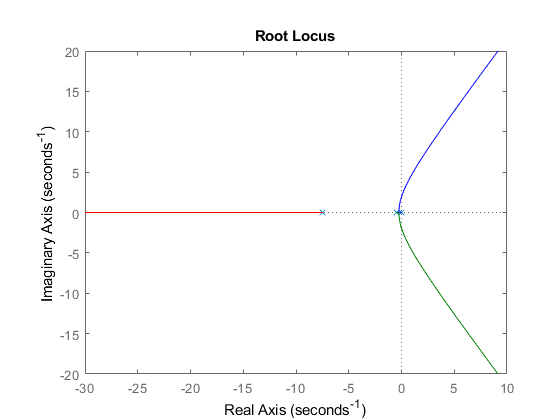


rlocus(Gmalha)

%% kmax teorico
Kx = 0.164

Kx = 0.1640

wx = 1.931

wx = 1.9310

% o valor de w teorico é proximo ao valor observado no gráfico

K = 1;  % Ganho maior que Kx

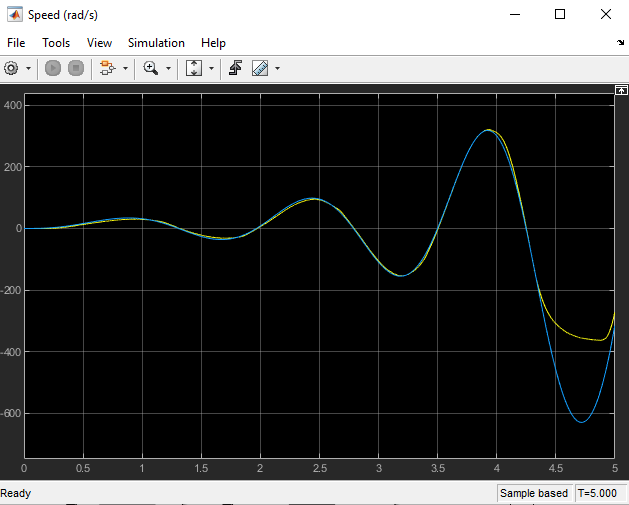

K = 0.1;  % Ganho menor que Kx

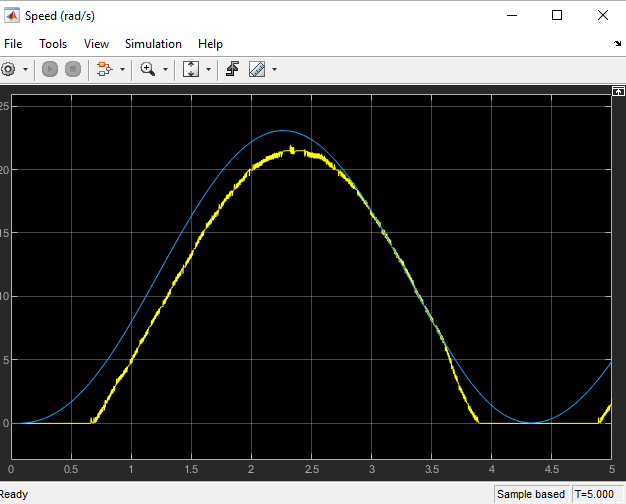

function [Eq] = ErroQuadratico(X,u,y,t)
% Esta função determina o erro quadrático
% entre a saída real e a saída do modelo.
% u - entrada real
% y - saída real
% t - tempo real
% X = [Km pm];

Km= X(1);
pm = X(2);

%%% Modelo

Gp = tf(Km, [1 pm]);

%%% Saida do modelo

ym = lsim(Gp, u, t);

%%% Erro quadrático

Eq = sum((y-ym).^2); %% cálculo do erro

% plot(t,y,t,ym,"linewidth", 2)

end